close('all'); clear; clc;
setmadsympath();
sympref("FloatingPointOutput",false);

## Geometry

The Sharp model considers a left-handed frame (North, West, Down).

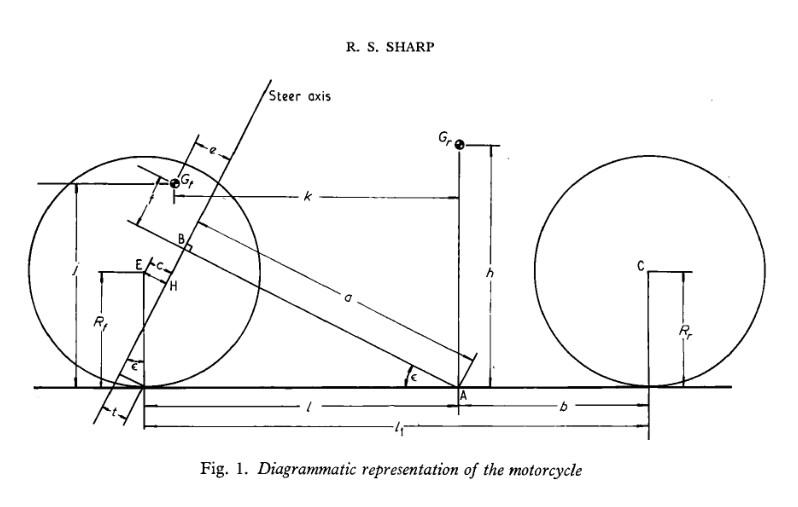

Create the caster frame:

caster = newParameters('varepsilon');
N = Frame;
Nc = N.orientNew('y',caster);

Solve for the front wheelbase $l$:

[a,an,l] = newParameters('a','a_n','l');
Pa = Point;
Pb = Pa.locateNew(a*Nc.x);
eqn = cos(caster) - a/(l + an/cos(caster));
l = solve(eqn,l);

Locate the front wheel center $E$:

rf = sym("r_f");
E = Pa.locateNew(l*N.x - rf*N.z);
rE = E.posFrom;
pprint(rE)

$$\left[\begin{array}{c} \frac{a-a_{n}}{c_{\varepsilon }}\\ 0\\ -r_{f} \end{array}\right]$$

Now locate the front wheel center relative to the intersection between the front chassis chord and the steering axis:

rBE = E.posFrom(Pb,Nc);
rBE = simplify(expand(rBE));

lx = rBE(1);
pprint(lx);

$$r_{f}\,s_{\varepsilon }-a_{n}$$


lz = rBE(3);
pprint(lz);

$$-\frac{r_{f}\,{c_{\varepsilon }}^{2}-a\,s_{\varepsilon }+a_{n}\,s_{\varepsilon }}{c_{\varepsilon }}$$

Now solve for the front chassis chord $a$ and the height $f$ of the front chassis mass center in the caster frame to obtain a simplifying substitution for $l_{z}$:

[e,f,j,k] = newParameters('e','f','j','k');
Gfa = Pa.locateNew(k*N.x - j*N.z);
Gh = Pb.locateNew(e*Nc.x + f*Nc.z);
sol_af = solve(Gh.posFrom(Gfa),[a,f]);

ovals = [a,f];
nvals = [sol_af.a,sol_af.f];
lz = subs(lz,ovals,nvals);
lz = simplify(expand(lz));
pprint(lz);

$$-\frac{a_{n}\,s_{\varepsilon }-j+e\,s_{\varepsilon }+{c_{\varepsilon }}^{2}\,j+{c_{\varepsilon }}^{2}\,r_{f}-c_{\varepsilon }\,k\,s_{\varepsilon }}{c_{\varepsilon }}$$

## Rigid bodies

t = sym('t');
N = Frame;
O = Point;

### Sharp origin

Orientation : 

yaw = DynamicVariable("psi",0,0);
Nyaw = N.orientNew('z',yaw.state);

Position :

v = sym('V');
px = DynamicVariable('x',0,v*t,v);
py = DynamicVariable('y',0,0);
Pa = O.locateNew(px.state*N.x + py.state*N.y);

### Rear chassis

Orientation:

lean = DynamicVariable("varphi",0,0);
Nlean = Nyaw.orientNew('x',lean.state);
pprint(Nlean.dcm)

$$\left[\begin{array}{ccc} c_{\psi } & -c_{\phi }\,s_{\psi } & s_{\psi }\,s_{\phi }\\ s_{\psi } & c_{\psi }\,c_{\phi } & -c_{\psi }\,s_{\phi }\\ 0 & s_{\phi } & c_{\phi } \end{array}\right]$$

Position:

h = newParameters('h');
Gb = Pa.locateNew(-h.*Nlean.z);
pprint(Gb.posFrom)

$$\left[\begin{array}{c} x-h\,s_{\psi }\,s_{\phi }\\ y+c_{\psi }\,h\,s_{\phi }\\ -c_{\phi }\,h \end{array}\right]$$

Rigid body:

mr = newParameters('m_r');

names = {
    'I_rx';
    'I_ry';
    'I_rz'
    };

[Irx,Iry,Irz] = newParameters(names{:});
Crxz = newParameters("C_rxz");
Ir = inertia(Irx,Iry,Irz,'Ixz',Crxz);
Bb = Body(Nlean,Gb,Ir,mr);

### Rear wheel

Orientation:

rr = sym("r_r");
pitch_r = DynamicVariable("theta_r",0,-v*t/rr);
Npitch_r = Nlean.orientNew('y',pitch_r.state);
pprint(Npitch_r.dcm);

$$\left[\begin{array}{ccc} c_{\psi }\,c_{\theta ,r}-s_{\psi }\,s_{\theta ,r}\,s_{\phi } & -c_{\phi }\,s_{\psi } & c_{\psi }\,s_{\theta ,r}+c_{\theta ,r}\,s_{\psi }\,s_{\phi }\\ c_{\theta ,r}\,s_{\psi }+c_{\psi }\,s_{\theta ,r}\,s_{\phi } & c_{\psi }\,c_{\phi } & s_{\psi }\,s_{\theta ,r}-c_{\psi }\,c_{\theta ,r}\,s_{\phi }\\ -c_{\phi }\,s_{\theta ,r} & s_{\phi } & c_{\theta ,r}\,c_{\phi } \end{array}\right]$$

Position:

b = sym('b');
Gr = Pa.locateNew(-b.*Nlean.x -rr.*Nlean.z);
pprint(Gr.posFrom)

$$\left[\begin{array}{c} x-b\,c_{\psi }-r_{r}\,s_{\psi }\,s_{\phi }\\ y-b\,s_{\psi }+c_{\psi }\,r_{r}\,s_{\phi }\\ -c_{\phi }\,r_{r} \end{array}\right]$$

Rigid body:

iry = newParameters('i_ry');
Irw = inertia(0,iry,0);
Br = Body(Npitch_r,Gr,Irw,0);

### Rear contact point

Cr = Gr.locateNew(rr*Nlean.z);
rGrCr = Cr.posFrom(Gr,Npitch_r);
pprint(rGrCr)

$$\left[\begin{array}{c} -r_{r}\,s_{\theta ,r}\\ 0\\ c_{\theta ,r}\,r_{r} \end{array}\right]$$

### Front chassis

Orientation:

Ncaster = Nlean.orientNew('y',caster);
steer = DynamicVariable("delta",0,0);
Nsteer = Ncaster.orientNew('z',steer.state);
pprint(Nsteer.dcm())

$$\left[\begin{array}{ccc} c_{\delta }\,c_{\psi }\,c_{\varepsilon }-c_{\phi }\,s_{\delta }\,s_{\psi }-c_{\delta }\,s_{\psi }\,s_{\phi }\,s_{\varepsilon } & s_{\delta }\,s_{\psi }\,s_{\phi }\,s_{\varepsilon }-c_{\psi }\,c_{\varepsilon }\,s_{\delta }-c_{\delta }\,c_{\phi }\,s_{\psi } & c_{\psi }\,s_{\varepsilon }+c_{\varepsilon }\,s_{\psi }\,s_{\phi }\\ c_{\psi }\,c_{\phi }\,s_{\delta }+c_{\delta }\,c_{\varepsilon }\,s_{\psi }+c_{\delta }\,c_{\psi }\,s_{\phi }\,s_{\varepsilon } & c_{\delta }\,c_{\psi }\,c_{\phi }-c_{\varepsilon }\,s_{\delta }\,s_{\psi }-c_{\psi }\,s_{\delta }\,s_{\phi }\,s_{\varepsilon } & s_{\psi }\,s_{\varepsilon }-c_{\psi }\,c_{\varepsilon }\,s_{\phi }\\ s_{\delta }\,s_{\phi }-c_{\delta }\,c_{\phi }\,s_{\varepsilon } & c_{\delta }\,s_{\phi }+c_{\phi }\,s_{\delta }\,s_{\varepsilon } & c_{\phi }\,c_{\varepsilon } \end{array}\right]$$

Position:

Pb = Pa.locateNew(a.*Ncaster.x);
Gh = Pb.locateNew(e.*Nsteer.x + f.*Nsteer.z);

Rigid body:

names = {
    'm_f';
    'I_fx';
    'I_fz'
    };

[mf,Ifx,Ifz] = newParameters(names{:});
If = inertia(Ifx,0,Ifz);
Bh = Body(Nsteer,Gh,If,mf);

### Front wheel

Orientation:

yaw_f = DynamicVariable("psi_f",1,0);
Nyaw_f = N.orientNew('z',yaw_f.state);

lean_f = DynamicVariable("varphi_f",1,0);
Nlean_f = Nyaw_f.orientNew('x',lean_f.state);

pitch_f = DynamicVariable("theta_f",0,-v*t/rf);
Npitch_f = Nlean_f.orientNew('y',pitch_f.state);

pprint(Npitch_f.dcm)

$$\left[\begin{array}{ccc} c_{\psi ,f}\,c_{\theta ,f}-s_{\psi ,f}\,s_{\theta ,f}\,s_{\phi ,f} & -c_{\phi ,f}\,s_{\psi ,f} & c_{\psi ,f}\,s_{\theta ,f}+c_{\theta ,f}\,s_{\psi ,f}\,s_{\phi ,f}\\ c_{\theta ,f}\,s_{\psi ,f}+c_{\psi ,f}\,s_{\theta ,f}\,s_{\phi ,f} & c_{\psi ,f}\,c_{\phi ,f} & s_{\psi ,f}\,s_{\theta ,f}-c_{\psi ,f}\,c_{\theta ,f}\,s_{\phi ,f}\\ -c_{\phi ,f}\,s_{\theta ,f} & s_{\phi ,f} & c_{\theta ,f}\,c_{\phi ,f} \end{array}\right]$$

Position:

rBWf = lx.*Nsteer.x + lz.*Nsteer.z;
Gf = Pb.locateNew(rBWf);

Rigid body:

ify = sym("i_fy");
Ifw = inertia(0,ify,0);
Bf = Body(Npitch_f,Gf,Ifw,0);

### Front contact point

Cf = Gf.locateNew(rf.*Nlean_f.z);
rGfCf = Cf.posFrom(Gf,Npitch_f);
pprint(rGfCf)

$$\left[\begin{array}{c} -r_{f}\,s_{\theta ,f}\\ 0\\ c_{\theta ,f}\,r_{f} \end{array}\right]$$

## Generalized coordinates

q = [
    yaw;
    px;
    py;
    lean;
    pitch_r;
    steer;
    yaw_f;
    lean_f;
    pitch_f
    ];

## Generalized speeds

wyaw = DynamicVariable("omega_psi",0,0);
vx = DynamicVariable("v_x",0,v);
vy = DynamicVariable("v_y",0,0);
wlean = DynamicVariable("omega_varphi",0,0);
wsteer = DynamicVariable("omega_delta",0,0);

u = [
    wyaw;
    vx;
    vy;
    wlean;
    wsteer
    ];

## Auxiliary speeds

Yr = DynamicVariable("Y_r",0,0);
Yf = DynamicVariable("Y_f",0,0);

Y = [
    Yr;
    Yf
    ];

## Holonomic constraints

spin_x = Nsteer.y(1) - Nlean_f.y(1);
spin_z = Nsteer.y(3) - Nlean_f.y(3);

hc = [
    spin_z;
    spin_x
    ];

hc = simplify(expand(hc));

pprint(hc)

$$\left[\begin{array}{c} c_{\delta }\,s_{\phi }-s_{\phi ,f}+c_{\phi }\,s_{\delta }\,s_{\varepsilon }\\ c_{\phi ,f}\,s_{\psi ,f}-c_{\delta }\,c_{\phi }\,s_{\psi }-c_{\psi }\,c_{\varepsilon }\,s_{\delta }+s_{\delta }\,s_{\psi }\,s_{\phi }\,s_{\varepsilon } \end{array}\right]$$

## Nonholonomic constraints

no_slip_r = noslip(Br,rGrCr,Nyaw);
no_slip_f = noslip(Bf,rGfCf,Nyaw_f);

nhc = [
    N.x.'*no_slip_r;
    N.x.'*no_slip_f
    ];

nhc = simplify(expand(nhc));
cons = ConstraintEquations(q,hc,nhc);
cons= simplify(cons);

## Kinematic equations

Ta = Pose(Nyaw,Pa);
Va = Twist(Ta).vector();

kdes = [
    wyaw.state - yaw.rate;
    vx.state - Va(4);
    vy.state - Va(5);
    wlean.state - lean.rate;
    wsteer.state - steer.rate
    ];

pprint(kdes);

$$\left[\begin{array}{c} \omega_{\psi }-\dot{\psi }\\ v_{x}-c_{\psi }\,\dot{x}-s_{\psi }\,\dot{y}\\ v_{y}-c_{\psi }\,\dot{y}+s_{\psi }\,\dot{x}\\ \omega_{\phi }-\dot{\phi }\\ \omega_{\delta }-\dot{\delta } \end{array}\right]$$

## Tire equations

TCr = Pose(Nyaw,Cr);
TCf = Pose(Nyaw_f,Cf);

VCr = Twist(TCr).vector();
vCr = VCr(4:5);

VCf = Twist(TCf).vector();
vCf = VCf(4:5);

rl = newParameters('sigma');

names = {
    'C_r1';
    'C_r2';
    'C_f1';
    'C_f2'
    };

[Cr1,Cr2,Cf1,Cf2] = newParameters(names{:});

slip_r = atan(vCr(2)/vCr(1));
slip_f = atan(vCf(2)/vCf(1));

eqYr = Yr.state + Cr1*slip_r - Cr2*lean.state;
eqYf = Yf.state + Cf1*slip_f - Cf2*lean_f.state;
eqY = [
    rl*Yr.rate + vCr(1)*eqYr;
    rl*Yf.rate + vCf(1)*eqYf
    ];

## Forces and moments

### Rear tire

Zr = newParameters('Z_r');
Fyr = Yr.state.*N.y;
Br.applyForce(Nyaw,Cr,Fyr + Zr.*N.z);

### Front tire

Zf = newParameters('Z_f');
Fyf = Yf.state.*N.y;
Bf.applyForce(Nyaw_f,Cf,Fyf + Zf.*N.z);

### Steering torque

Msteer = DynamicVariable("tau_delta",0,0);
Csteer = newParameters('C_delta');
Mz = (Msteer.state - Csteer*steer.rate).*N.z;
Bh.applyMoment(Nsteer,Mz);
Bb.applyMoment(Nsteer,-Mz);

### Gravity

B = [
    Bb;
    Br;
    Bh;
    Bf
    ];

g = newParameters('g');
fp = @(b)b.MassCenter;
fFg = @(b)(b.Mass*g).*N.z;
fg = @(b)b.applyForce(N,fp(b),fFg(b));
arrayfun(fg,B);

## Equations of motion

F = Msteer;
eom = appellsMethod(q,u,kdes,B,F,cons,Y,eqY);

## Linearized equations of motion

eoml = simplify(linearize(eom));
eqns = sym(eoml);

### Geometric simplifications

ovals = [a,f];
nvals = [sol_af.a,sol_af.f];
nvals = simplify(expand(nvals));
eqns = simplify(expand(subs(eqns,ovals,nvals)));

## Sharp's equations

xs = [
    lean;
    steer;
    wyaw;
    vy;
    wlean;
    wsteer;
    Yr;
    Yf
    ];

P = jacobian(eoml.States.state,xs.state);
eqns_sharp = P.'*eqns;

[Ms,fs] = massMatrixForm(eqns_sharp,xs.state);
[Hs,gs] = equationsToMatrix(fs,xs.state);

ovals = j*sin(caster);
nvals = a - cos(caster)*k + e;
Hs = subs(Hs,ovals,nvals);

Gs = jacobian(-gs,eoml.Inputs.state);

eoms = LinearizedMotionEquations(xs,Ms,Hs,Gs,F);
eoms = simplify(eoms);
disp(eoms)

States : 


$$\left[\begin{array}{cccccccc} \phi & \delta & \omega_{\psi } & v_{y} & \omega_{\phi } & \omega_{\delta } & Y_{r} & Y_{f} \end{array}\right]$$

Mass Matrix : 


$$\left[\begin{array}{cccccccc} 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & I_{\mathrm{fx}}+I_{\mathrm{rz}}-I_{\mathrm{fx}}\,{c_{\varepsilon }}^{2}+I_{\mathrm{fz}}\,{c_{\varepsilon }}^{2}+k^{2}\,m_{f} & k\,m_{f} & C_{\mathrm{rxz}}-\frac{I_{\mathrm{fx}}\,\sin\left(2\,\varepsilon \right)}{2}+\frac{I_{\mathrm{fz}}\,\sin\left(2\,\varepsilon \right)}{2}+j\,k\,m_{f} & I_{\mathrm{fz}}\,c_{\varepsilon }+e\,k\,m_{f} & 0 & 0\\ 0 & 0 & k\,m_{f} & m_{f}+m_{r} & h\,m_{r}+j\,m_{f} & e\,m_{f} & 0 & 0\\ 0 & 0 & C_{\mathrm{rxz}}-\frac{I_{\mathrm{fx}}\,\sin\left(2\,\varepsilon \right)}{2}+\frac{I_{\mathrm{fz}}\,\sin\left(2\,\varepsilon \right)}{2}+j\,k\,m_{f} & h\,m_{r}+j\,m_{f} & I_{\mathrm{fz}}+I_{\mathrm{rx}}+I_{\mathrm{fx}}\,{c_{\varepsilon }}^{2}-I_{\mathrm{fz}}\,{c_{\varepsilon }}^{2}+h^{2}\,m_{r}+j^{2}\,m_{f} & I_{\mathrm{fz}}\,s_{\varepsilon }+e\,j\,m_{f} & 0 & 0\\ 0 & 0 & I_{\mathrm{fz}}\,c_{\varepsilon }+e\,k\,m_{f} & e\,m_{f} & I_{\mathrm{fz}}\,s_{\varepsilon }+e\,j\,m_{f} & m_{f}\,e^{2}+I_{\mathrm{fz}} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & \sigma & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & \sigma \end{array}\right]$$

Forcing Matrix : 


$$\left[\begin{array}{cccccccc} 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & -V\,k\,m_{f} & 0 & \frac{V\,i_{\mathrm{fy}}}{r_{f}}+\frac{V\,i_{\mathrm{ry}}}{r_{r}} & \frac{V\,i_{\mathrm{fy}}\,s_{\varepsilon }}{r_{f}} & -b & \frac{a-a_{n}}{c_{\varepsilon }}\\ 0 & 0 & -V\,\left(m_{f}+m_{r}\right) & 0 & 0 & 0 & 1 & 1\\ g\,\left(h\,m_{r}+j\,m_{f}\right) & e\,g\,m_{f}-Z_{f}\,a_{n} & -V\,h\,m_{r}-V\,j\,m_{f}-\frac{V\,i_{\mathrm{fy}}}{r_{f}}-\frac{V\,i_{\mathrm{ry}}}{r_{r}} & 0 & 0 & -\frac{V\,c_{\varepsilon }\,i_{\mathrm{fy}}}{r_{f}} & 0 & 0\\ e\,g\,m_{f}-Z_{f}\,a_{n} & -s_{\varepsilon }\,\left(Z_{f}\,a_{n}-e\,g\,m_{f}\right) & -V\,e\,m_{f}-\frac{V\,i_{\mathrm{fy}}\,s_{\varepsilon }}{r_{f}} & 0 & \frac{V\,c_{\varepsilon }\,i_{\mathrm{fy}}}{r_{f}} & -C_{\delta } & 0 & -a_{n}\\ C_{\mathrm{r2}}\,V & 0 & C_{\mathrm{r1}}\,b & -C_{\mathrm{r1}} & 0 & 0 & -V & 0\\ C_{\mathrm{f2}}\,V & V\,\left(C_{\mathrm{f1}}\,c_{\varepsilon }+C_{\mathrm{f2}}\,s_{\varepsilon }\right) & -\frac{C_{\mathrm{f1}}\,\left(a-a_{n}\right)}{c_{\varepsilon }} & -C_{\mathrm{f1}} & 0 & C_{\mathrm{f1}}\,a_{n} & 0 & -V \end{array}\right]$$

Input Matrix : 


$$\left[\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ 1\\ 0\\ 0 \end{array}\right]$$

Inputs : 


$$\tau_{\delta }$$

## State space

% matlabFunction(eoms,"sharpMotorcycle");